

graphSet;

repertoire = './'; % Chemin d'acces au code compile (NB: enlever le ./ sous Windows)
executable = 'Exercice7'; % Nom de l'executable (NB: ajouter .exe sous Windows)
input = '7_3_a.in'; % Nom du fichier d'entree de base

cb_gauche = 'harmonique';
cb_droit = 'sortie';

output = '7_3_a';
cmd = sprintf('wsl %s%s %s cb_gauche=%s cb_droit=%s  output=%s', repertoire, executable, input, cb_gauche,cb_droit,output);
disp(cmd);

wsl ./Exercice7 7_3_a.in cb_gauche=harmonique cb_droit=sortie  output=7_3_a


system(cmd);

fichier = output;
data = load([fichier,'_u.out']);
x = data(:,1);
u = data(:,2);
data = load([fichier,'_E.out']);
t = data(:,1);
E = data(:,2);
data = load([fichier,'_f.out']);
f = data(:,2:end);

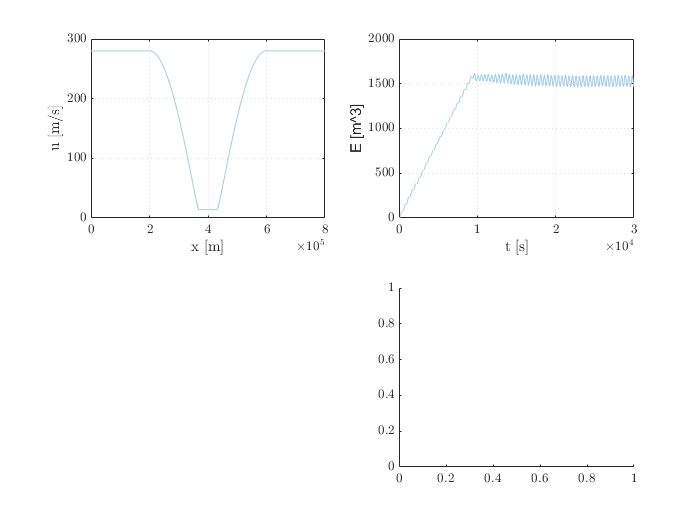


%% Figures %%
%%%%%%%%%%%%%
figure('Name',['Analyse de ' fichier])
subplot(2,2,1)
plot(x,u)
grid
xlabel('x [m]')
ylabel('u [m/s]')

subplot(2,2,2)
plot(t,E)
grid
xlabel('t [s]')
ylabel('E [m^3]')

subplot(2,2,4)

pcolor(x,t,f)

Error using pcolor (line 58)
Color data input must be a matrix.

shading interp
colormap bone
c = colorbar;
xlabel('x [m]')
ylabel('t [s]')
ylabel(c,'f(x,t) [m]')

subplot(2,2,3)
h = plot(x,f(1,:));
grid
xlabel('x [m]')
ylabel('f(x,t) [m]')
ht = title('t=0 s');
ylim([min(f(:)),max(f(:))])
% for i=2:length(t)
%     pause(.01)
%     if ~ishandle(h)
%         break % Arrete l'animation si la fenetre est fermee
%     end
%     set(h,'YData',f(i,:))
%     set(ht,'String',sprintf('t=%0.2f s',t(i)))
% end


fig = figure('visible','on')

fig =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [584 630 560 420]
       Units: 'pixels'

  Show all properties



n = length(t)

n = 11662

for i=1:n
    
    
     plot(x,f(i,:),'o');
    if ~ishandle(fig)
         break % Arrete l'animation si la fenetre est fermee
    end
    ylim([-5 5])
    pause(0.005)
end

